# Use a Simulink Thermal Model in System-Level Models

Run this script to simulate a previously-generated Simulink® ROM thermal model of an IPMSM with housing water jacket and self-ventilated cooling, integrated in a Simulink and Simscape™ system-level vehicle model, including cooling system models.

This script does not require Motor-CAD™ to run, as the ROM model has been previously generated and saved. 

To re-generate the ROM model, run the `GenerateSimulinkThermalModel.mlx` script (requires Motor-CAD).

## Overview of the Simulink ROM Thermal Model

Open the pre-generated model:

modelName1 = 'e8_IPMSM_HWJandVent_ROM';
open_system(modelName1);

The ROM model consists of 4 subsystems:

- Coolant Interface

- Loss Maps from Motor-CAD Lab

- Power Loss Distributor

- Interpolated State-Space Thermal Model

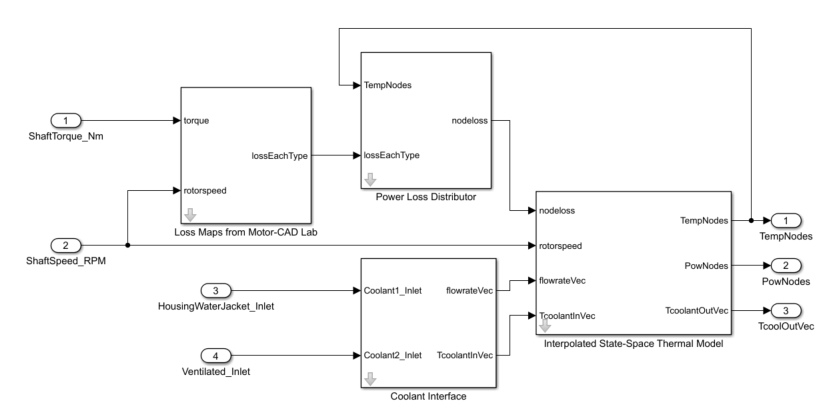

### Coolant Interface

The *Coolant Interface* subsystem re-organizes the signals from the cooling system inlet ports to be used by the *Interpolated State-Space Thermal Model* subsystem. It groups the flow rate of each cooling system into a vector of flow rates, and the inlet temperature of each cooling system into a vector of coolant inlet temperatures.

### Loss Maps from Motor-CAD Lab

The *Loss Maps from Motor-CAD Lab* subsystem computes how much loss of each type is produced in the motor at a given shaft torque and shaft speed. It interpolates the loss tables from the Motor-CAD Lab model.

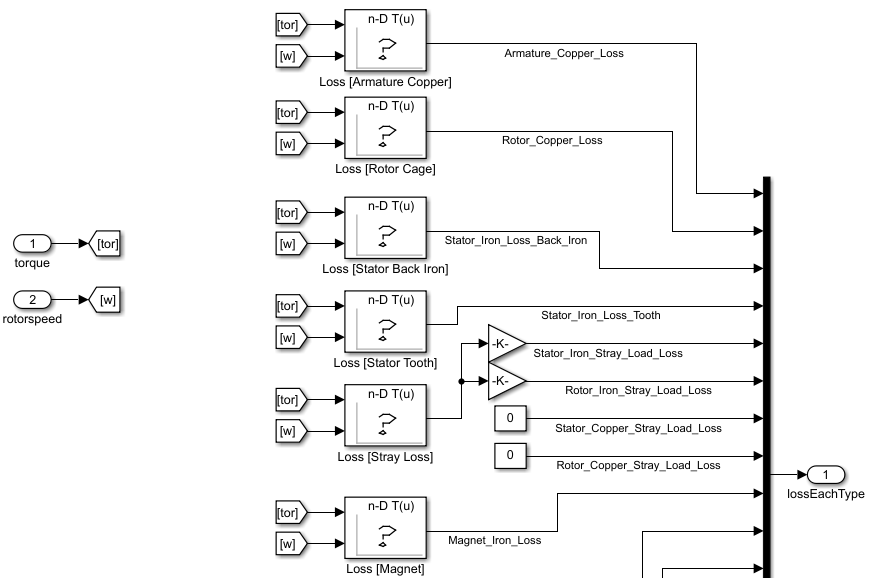

### Power Loss Distributor

The *Power Loss Distributor* subsystem distributes the losses into the thermal model nodes. The assumption is that the losses of each type have a constant distribution to the thermal nodes. Hence, the loss at each particular thermal node is the sum of how much loss of each type is produced and the proportion of it that corresponds to this node.

### Interpolated State Space Thermal Model

The *Interpolated State-Space Thermal Model* implements the state space model:


$$\frac{\textrm{dx}}{\textrm{dt}}\;=\;A\;x+B\;p$$


where:

- ***x*** is the vector of node temperatures (the states), *Tnodes*

- ***p*** is the vector of node losses, *nodeloss*

- ***A*** and ***B*** are the state-space matrices, *Amat* and *Bmat*. 

***A*** and ***B ***are interpolated from a set of state-space matrices at different operating points (speed, coolant flow rates, and coolant inlet temperatures):

- A = Afun(w, fr, Tin)

- B = Bfun(w, fr, Tin)

This type of model is commonly known as *Linear Parameter Varying model* (**LPV model**).

To correctly predict the coolant heat flow rate, the model needs to apply a loss correction to the upstream fluid nodes, as heat cannot be conducted upstream of the flow. The *Coolant Heatflow Adjustment* subsystem applies this correction.

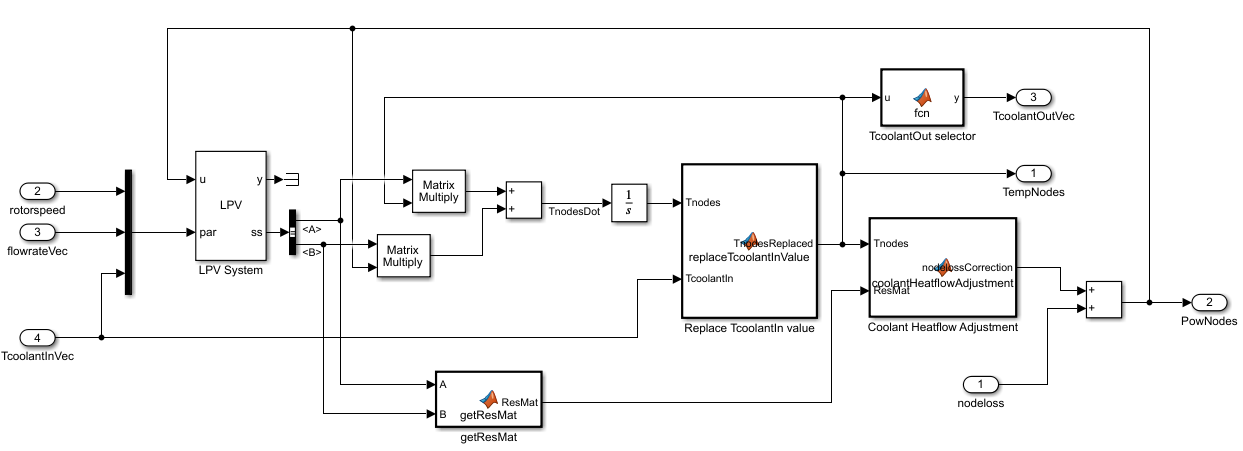

bdclose(modelName1);

## Run the ROM in a Drive Cycle Simulation

Open a model set up for a drive cycle simulation:

modelName2 = 'DriveCycle_e8_IPMSM_HWJandVent_ROM';
open_system(modelName2);

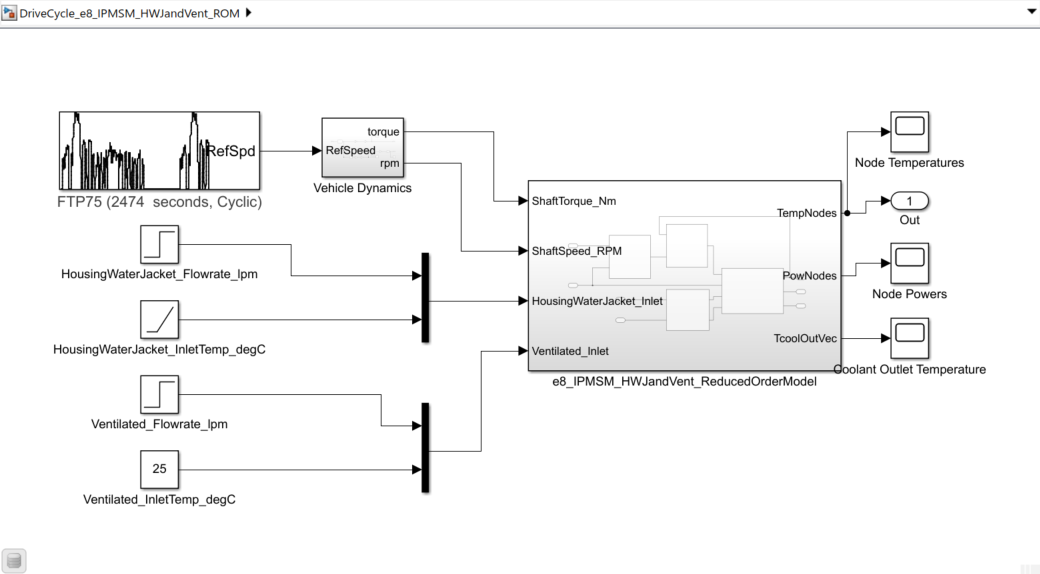

The model comprises the automatically-generated Simulink ROM subsystem, a* Vehicle Dynamics* subsystem, a drive cycle block, and some step and ramp blocks for a simple cooling system test.

Run the model and observe how the *Node Temperatures* evolve in this scenario:

simTime = 900; % [s]
tic;
sim(modelName2, 'StopTime', num2str(simTime));
realTime = toc

realTime = 55.0359


disp(['Runs ', num2str(simTime/realTime), ' times faster than real time']);

Runs 16.353 times faster than real time


## Integrate the ROM in a Simscape System-Level Model

Open a Simscape™ system-level model of an electric vehicle powertrain and motor cooling systems:

modelName3 = 'SimscapeSystemLevel_e8_IPMSM_HWJandVent_ROM';
open_system(modelName3);

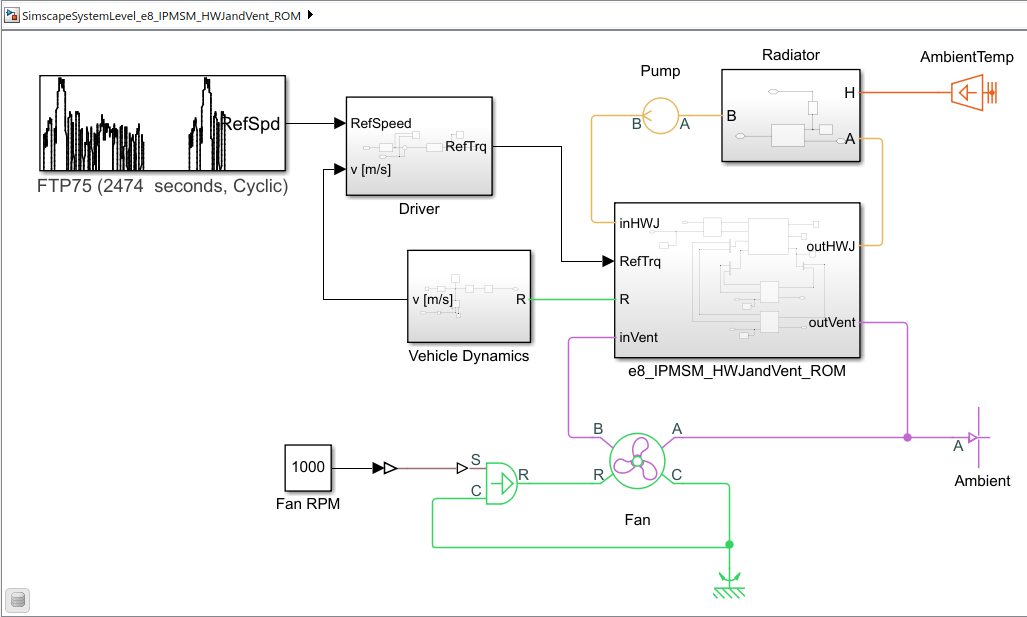

The model comprises the automatically-generated Simulink ROM subsystem (with Simscape interfaces), a* Vehicle Dynamics* subsystem, a *Driver* subsystem, a thermal liquid circuit with a *Pump, Radiator* and a gas circuit with a *Fan.* You can also find the same drive cycle block from the previous model.

The *e8_IPMSM_HWJandVent_ROM* subsystem contains the automatically-generated Simulink ROM subsystem and some interface subsystems.:

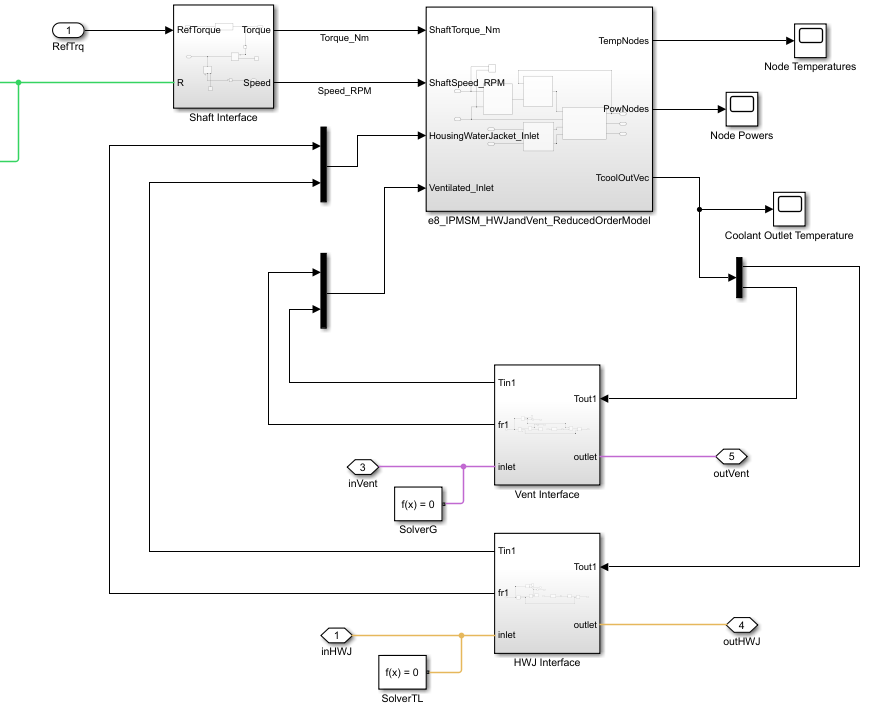

The *Interface* subystems allow you to use the Simulink ROM model with physical models implemented in Simscape.

The *Driver* subsystem represents a human driver controlling the speed of the vehicle by providing a torque command to the powertrain.

In this case, the control algotihm is a simple PI controller.

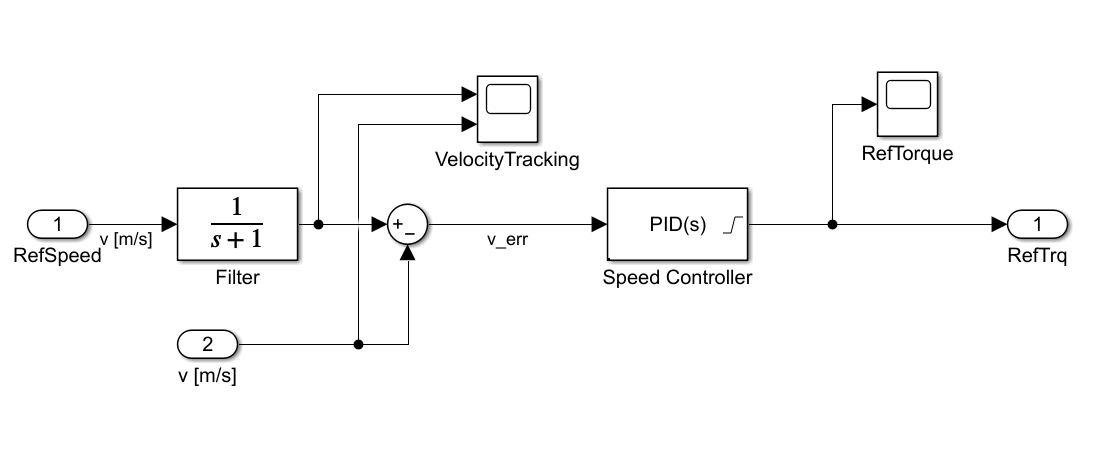

The *Vehicle Dynamics* subsystem comprises the vehicle mass, the friction, and the motor gear:

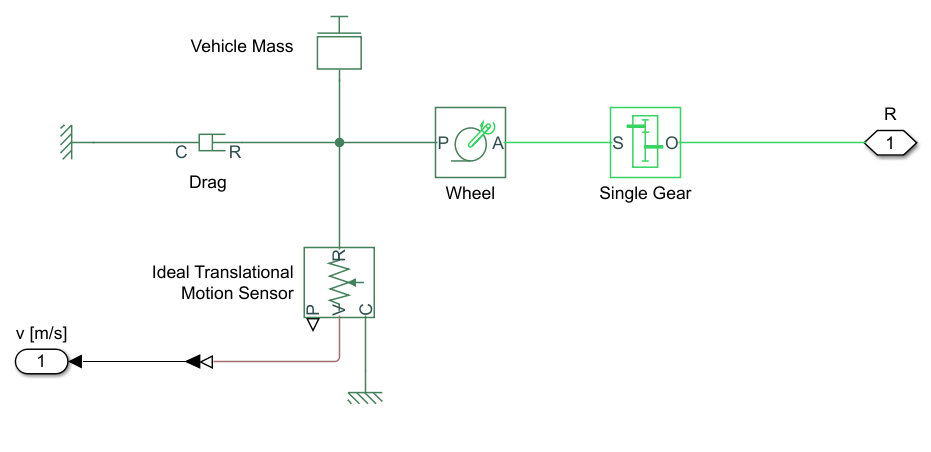

Run the model and observe how the *Node Temperatures* evolve in this scenario:

simTime = 900; % [s]
tic;
sim(modelName3, 'StopTime', num2str(simTime));
realTime = toc

realTime = 41.7035

disp(['Runs ', num2str(simTime/realTime), ' times faster than real time']);

Runs 21.5809 times faster than real time


*Copyright 2022-2025 The MathWorks, Inc.*